% Based on the tutorial at https://se.mathworks.com/help/signal/examples/measuring-signal-similarities.html
% Used Matlab 2020a

clear;

SAVE_PLOT = false;
PLOT_DEBUG = false; 

load('heading_ts_vars.mat');
sig1_orig_change_rate = trajectory_angle_change_rate_fullsamplerate; % Fruit fly angular velocity (original) time series
sig1_orig = trajectory_angle_fullsamplerate; % Fruit fly heading (original) time series
t_orig = t_fullsamplerate;                   % Time stamps of original fruit fly heading time series
Fs_orig = 1 / 1e-4;                          % Sampling rate of original time series
sig1 = trajectory_angle_subsampled;          % Signal 1: Subsampled of fruit fly heading time series
sig2 = simulation_theta_ts_median_subsampled;% Signal 2: Simulation of head tracking circuit time series (same sampling rate as subsampled)
t    = t_subsampled;                         % Time stamps of subsampled time series
Fs   = 10;                                   % Sampling rate of subsampled time series

## Heading tracking error

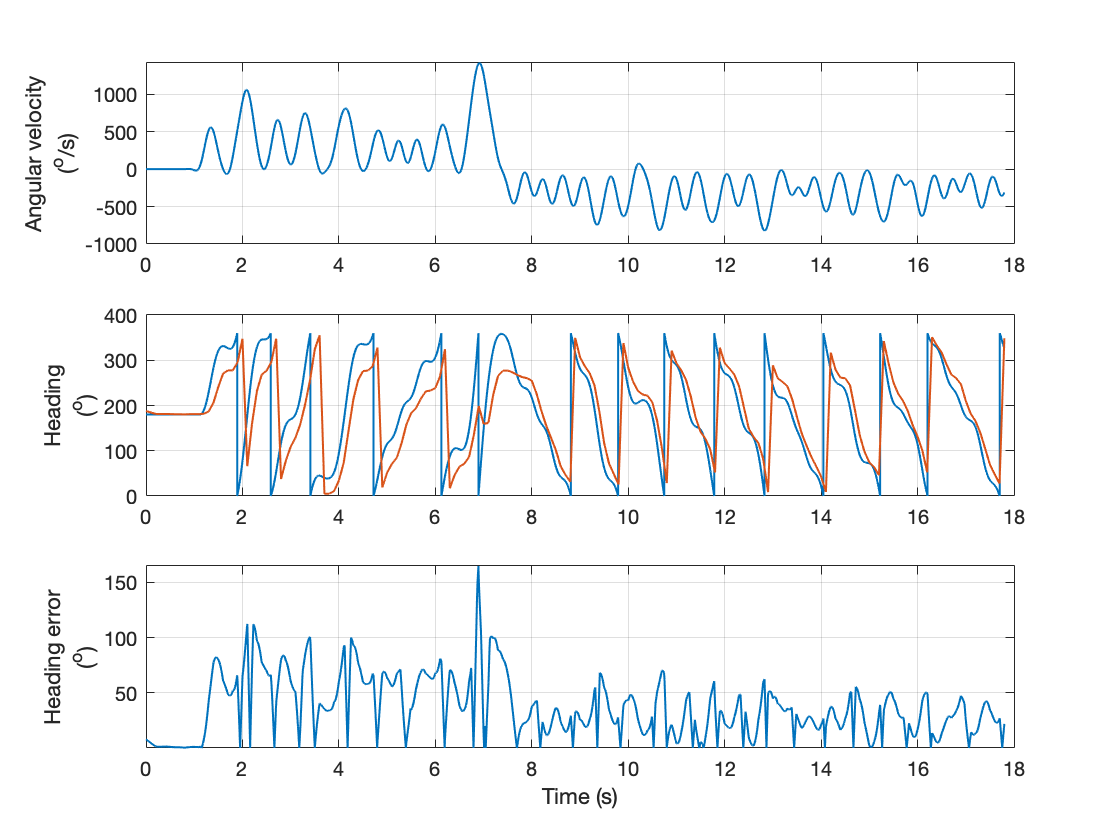

% Upsample the simulated heading trajectory
sig2_upsampled = interp1(t, sig2, t_orig); % Returns NaN for samples outside the defined domain when using linear interpolation
start_nans = min(find(isnan(sig2_upsampled))); % Find the first NaN produced by the interp1 at the end of the vector
% Chop all signals to the same length rejecting NaN values
keep = [1:start_nans-1];
sig2_upsampled_chopped = sig2_upsampled(keep); % Reject the NaN values at the end of the vector
sig1_orig_change_rate_chopped = sig1_orig_change_rate(keep);
sig1_orig_chopped = sig1_orig(keep);
t_orig_chopped = t_orig(keep);

fig = figure();
ax1(1) = subplot(3,1,1);
plot(t_orig_chopped, sig1_orig_change_rate_chopped, 'LineWidth', 1);
grid on;
xlim([0 18]);
ylabel({'Angular velocity'; '(^o/s)'});

ax1(2) = subplot(3,1,2);
plot(t_orig_chopped, sig1_orig_chopped, 'LineWidth', 1);
if PLOT_DEBUG
    plot(t_orig_chopped, sig1_orig_chopped-180);
    hold on;
    plot(t_orig_chopped, abs(sig1_orig_chopped-180));
end
sig1_orig_chopped_abs = abs(sig1_orig_chopped-180);
grid on;
xlim([0 18])
ylabel({'Heading'; '(^o)'});
hold on;

%ax1(3) = subplot(4,1,3);
plot(t_orig_chopped, sig2_upsampled_chopped, 'LineWidth', 1);
if PLOT_DEBUG
    plot(t_orig_chopped, sig2_upsampled_chopped-180);
    hold on;
    plot(t_orig_chopped, abs(sig2_upsampled_chopped-180));
end
sig2_upsampled_chopped_abs = abs(sig2_upsampled_chopped-180);
grid on;
xlim([0 18]);
ylabel({'Heading'; '(^o)'});

% Filtering to get rid of the sharp gaps in this last one
d1 = sig2_upsampled_chopped_abs;
% Find local minima and maxima
[pks_neg, pks_neg_loc] = findpeaks(-d1+100,'MinPeakDistance',100, 'MinPeakProminence',90,'MinPeakHeight',90); % minima
[pks_pos, pks_pos_loc] = findpeaks(d1, 'MinPeakDistance',100, 'MinPeakProminence',90,'MinPeakHeight',90); % maxima
pks_pos_loc = [pks_pos_loc pks_pos_loc(end)+999]; % Add an extra last maximum because it does not detect it
pks_pos = [pks_pos d1(pks_pos_loc(end))]; % Add the extra maximum at the end
% Find narrow valleys (maximum-minimum-maximum) to remove
Midx_diffs = abs(pks_pos_loc - pks_neg_loc'); % Get the differences of each minimum from all maxima
Midx_mask = Midx_diffs < Fs_orig / 10 / 1.5;  % Keep only valleys that narrow enough
pks_pos_loc_repeated = repmat(pks_pos_loc,length(pks_neg_loc)); % Prepare 
Midx = pks_pos_loc_repeated(Midx_mask); % Returns one list of all the pairs of positive peaks that should be connected with smoothed lines
Midx2D = reshape(Midx, [2 length(Midx)/2])'; % Reshape it in pairs of indeces marking the valleys
% Iterate over each pair of indeces and remove valleys
for i = 1:size(Midx2D, 1)
    x12 = Midx2D(i,:);
    y12 = d1(x12);
    replacement_vec = linspace(y12(1), y12(2), x12(2) - x12(1));
    d1([x12(1):x12(2)-1]) = replacement_vec;
end
sig2_upsampled_chopped_abs_2 = d1;
if PLOT_DEBUG
    plot(t_orig_chopped(pks_neg_loc), zeros(1,length(pks_neg_loc)), 'kx'); % Plot the minima
    plot(t_orig_chopped(pks_pos_loc), d1(pks_pos_loc), 'rx'); % Plot the maxima
    plot(t_orig_chopped(Midx), d1(Midx), 'bo');
    plot(t_orig_chopped, sig2_upsampled_chopped_abs_2);
end

% Error
diff7 = abs(sig1_orig_chopped_abs - sig2_upsampled_chopped_abs_2);

ax1(4) = subplot(3,1,3);
plot(t_orig_chopped, diff7, 'LineWidth', 1);
grid on;
ylabel({'Heading error'; '(^o)'});
xlabel('Time (s)');
axis tight
linkaxes([ax1(1),ax1(2),ax1(3),ax1(4)],'x');


% Save the figure in a file
if SAVE_PLOT
    output_plot_file_basename = 'Plots/heading_tracking_error';
    Resolution = 300;
    set(findall(gcf,'-property','FontSize'),'FontSize',10);
    set(gcf, 'Units', 'centimeters', 'Position', [0 0 10 10]);
    axis tight;
    my_save_fig(gcf, output_plot_file_basename, Resolution);
end

[P3,f3] = periodogram(sig2_upsampled_chopped - mean(sig2_upsampled_chopped),[],[],Fs_orig,'power'); 

[Cxy,f] = mscohere(sig1,sig2,[],[],[],Fs);
Pxy     = cpsd(sig1,sig2,[],[],[],Fs);
phase   = -angle(Pxy)/pi*180;
[pks,locs] = findpeaks(Cxy,'MinPeakHeight',0.5);

figure
subplot(2,1,1)
% Empty 

subplot(3,1,2)
plot(f3,P3, 'LineWidth', 1)
title('Power Spectral Density')
ylabel('Spectral Density (^{o^2})')
%xlabel('Frequency (Hz)')
grid on
axis tight
xlim([0 4])

% Print the frequencies at the peaks of FFT
[pd_pks, pd_pks_loc] = findpeaks(P3,'MinPeakDistance',1, 'MinPeakProminence',90,'MinPeakHeight',90);
disp('FFT peaks at (Hz):');

FFT peaks at (Hz):


disp(f3(pd_pks_loc)');

  Columns 1 through 9

    0.2289    0.3433    0.4578    0.5722    0.6485    0.9155    1.0681    1.1826    1.3733

  Columns 10 through 11

    1.8692    2.0218



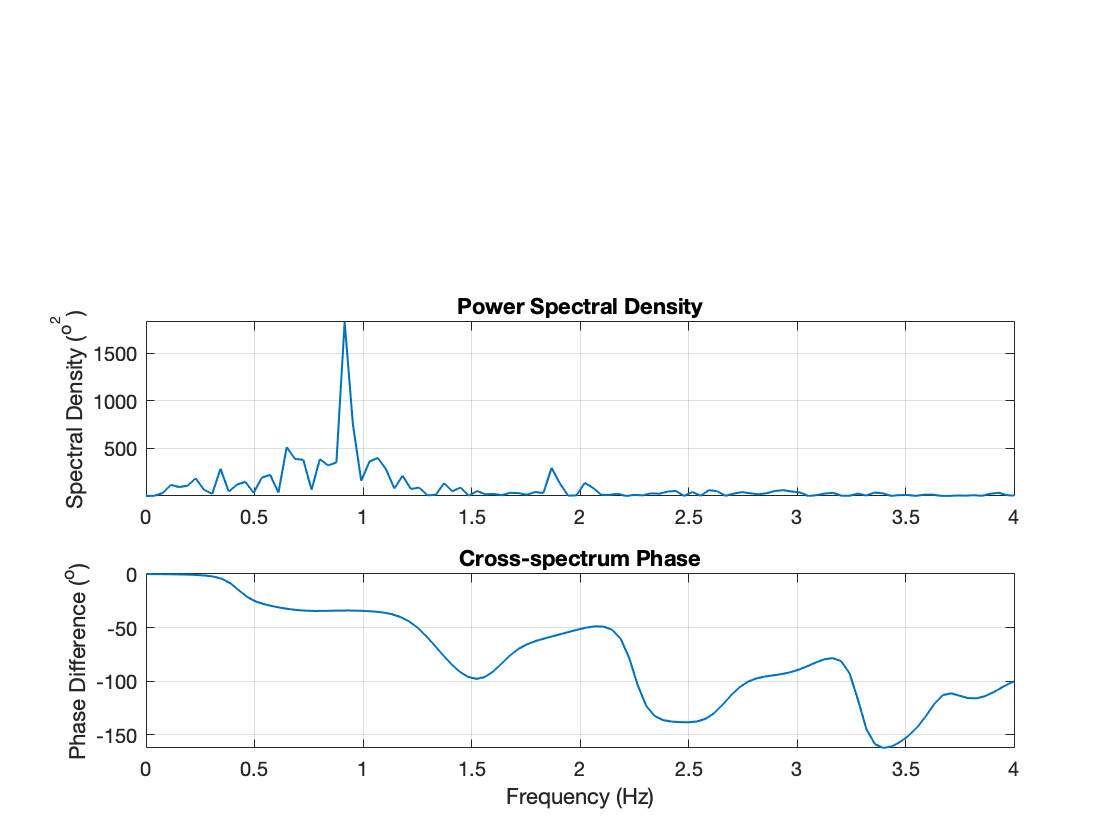



subplot(3,1,3)
plot(f,phase, 'LineWidth', 1)
title('Cross-spectrum Phase')
ylabel('Phase Difference (^o)')
xlabel('Frequency (Hz)')
grid on
axis tight;
xlim([0 4])


% Save the figure in a file
if SAVE_PLOT
    output_plot_file_basename = 'Plots/spectral_characteristics';
    Resolution = 300;
    set(findall(gcf,'-property','FontSize'),'FontSize',10);
    set(gcf, 'Units', 'centimeters', 'Position', [0 0 8.5 10]);
    my_save_fig(gcf, output_plot_file_basename, Resolution);
end